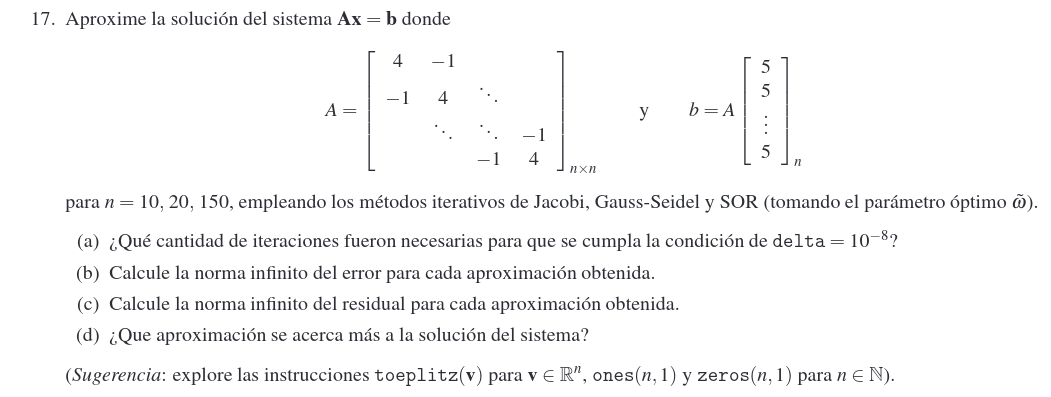

n = 10

n = 10

B = 5*ones(n,1)

B =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


I = diag(diag(4 * ones(n,n)))

I =      4     0     0     0     0     0     0     0     0     0
     0     4     0     0     0     0     0     0     0     0
     0     0     4     0     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0     0
     0     0     0     0     4     0     0     0     0     0
     0     0     0     0     0     4     0     0     0     0
     0     0     0     0     0     0     4     0     0     0
     0     0     0     0     0     0     0     4     0     0
     0     0     0     0     0     0     0     0     4     0
     0     0     0     0     0     0     0     0     0     4


L = triu((-1 * ones(n))) - triu((-1 * ones(n)),-1); 
L = L * -1

L =      0     0     0     0     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0    -1     0


U = tril((-1 * ones(n))) - tril((-1 * ones(n)),1);
U = U * -1

U =      0    -1     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0


A = I+L+U

A =      4    -1     0     0     0     0     0     0     0     0
    -1     4    -1     0     0     0     0     0     0     0
     0    -1     4    -1     0     0     0     0     0     0
     0     0    -1     4    -1     0     0     0     0     0
     0     0     0    -1     4    -1     0     0     0     0
     0     0     0     0    -1     4    -1     0     0     0
     0     0     0     0     0    -1     4    -1     0     0
     0     0     0     0     0     0    -1     4    -1     0
     0     0     0     0     0     0     0    -1     4    -1
     0     0     0     0     0     0     0     0    -1     4



eig(A)

ans =     2.0810
    2.3175
    2.6903
    3.1692
    3.7154
    4.2846
    4.8308
    5.3097
    5.6825
    5.9190



x0 = ones(n,1);

J = -inv(I)*(U+L);
Pj = max(abs(eig(J)));
W = 2 / (1 + sqrt(1 - Pj^2));

X = jacobi (A, B,x0, 10e-8, 100)

k = 22

err = 4.3306e-07

X =     1.8301
    2.3205
    2.4518
    2.4869
    2.4956
    2.4956
    2.4869
    2.4518
    2.3205
    1.8301



Z = gseid (A, B, x0, 10e-8, 100)

k = 14

Z =     1.8301
    2.3205
    2.4518
    2.4869
    2.4956
    2.4956
    2.4869
    2.4518
    2.3205
    1.8301



Y = sor (A, B, x0, W, 10e-8, 100)

k = 11

Y =     1.8301
    2.3205
    2.4518
    2.4869
    2.4956
    2.4956
    2.4869
    2.4518
    2.3205
    1.8301
